# Demo Fast Gaussian Simulation

## Exemple 1: 1D

Define the simulation parameters

sim.s=100; % simulation size 
sim.n=10; % number of simulation

Define the covariance parameters

covar.model = 'gaussian'; % type of covariance function, see covarIni.m for option
covar.range = 5; % range of covariance, vector same size as sim.s.
covar.var = 1; % variance

Compute

tic; res = FGS(sim,covar); toc

Elapsed time is 0.034007 seconds.


Display result

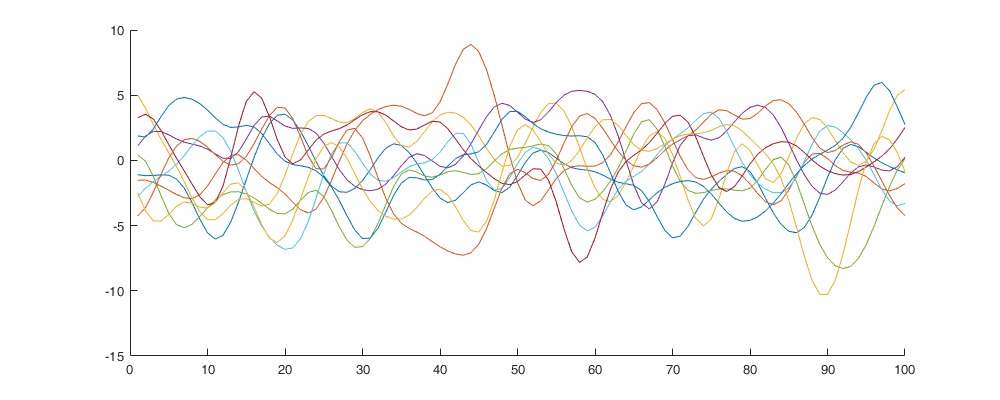

figure('position',[0 0 1000 400]);  hold on;
for i=1:sim.n
    plot(res{i}');
end

## Exemple 2: 2D

Define the simulation parameters

sim.s=[100 100];
sim.n=6;
sim.DisplayProgression=true; % Display a progression bar
sim.tol = 1e-10; % Tolerence in the acuracy of the covariance function map.

Define the covariance parameters

covar(1).model = 'k-bessel';
covar(1).range = [4 8];
covar(1).azimuth = 0; % orientation of the covariance
covar(1).var = 1;
covar(1).alpha = 5; % parameter of covariance function (depend on the model chosen, see covarIni.m for option)

covar(2).model = 'nugget';
covar(2).range = [eps eps];
covar(2).var = .1;

Compute

tic; res = FGS(sim,covar); toc

Elapsed time is 0.435471 seconds.


Display result

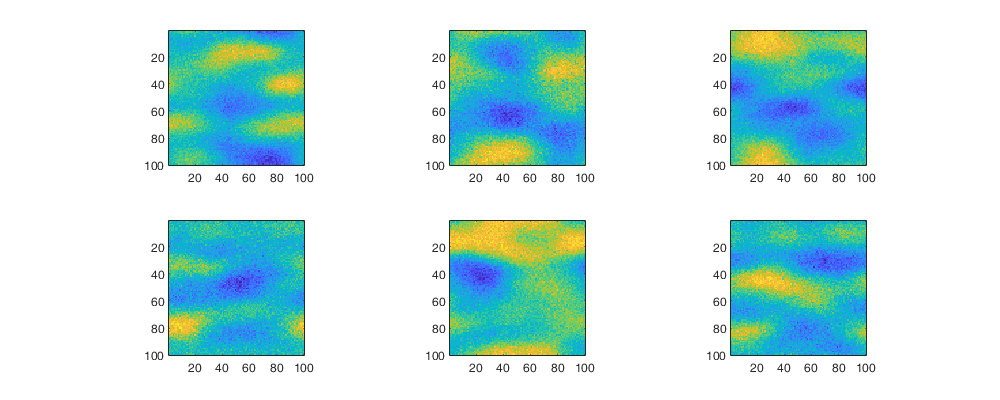

figure('position',[0 0 1000 400]); 
for i=1:sim.n
    subplot(ceil(sim.n/ceil(sqrt(sim.n))),ceil(sqrt(sim.n)), i)
    imagesc(res{i}); axis equal tight;
end

## Exemple 2: 3D

sim.s=[100 100 100];
sim.n = 1;
covar.model = 'k-bessel';
covar.range = [4 10 15];
covar.azimuth = [0 0];
covar.c0 = 3;
covar.alpha = 5;

tic;res = FGS(sim,covar);toc;

Elapsed time is 35.212305 seconds.


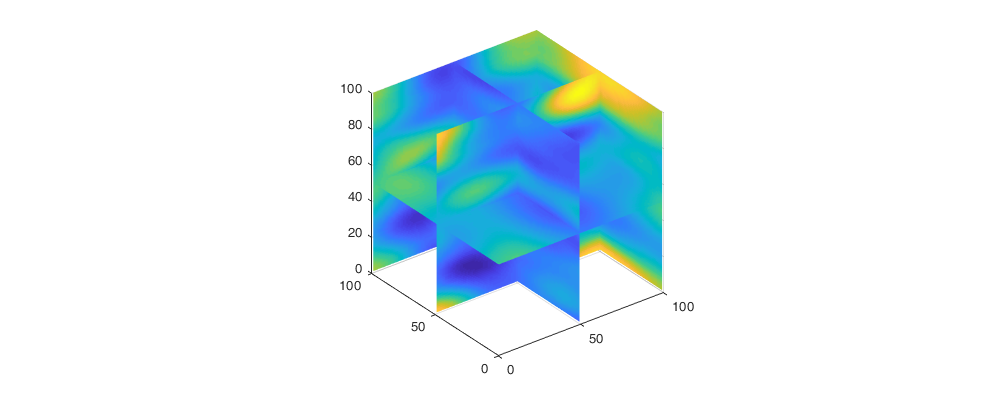

figure('position',[0 0 1000 400]); 
for i=1:sim.n
    subplot(ceil(sim.n/ceil(sqrt(sim.n))), ceil(sqrt(sim.n)), i)
    s=slice(res{i},0:50:100,0:50:100,[0 50]);
    axis equal
    set(s,'edgecolor','none')
end